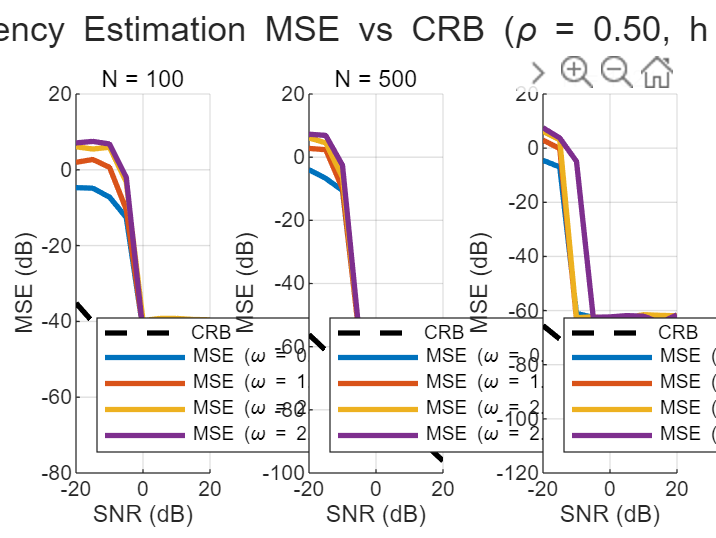

 %%%%%%%%----参数定义赋值--1.2 -----%%%%%%%%
    a0 = 1;
    N_values = [100, 500, 1024]; % 样本数量
    N_values_1 = linspace(20, 200, 10);
    omega_values = pi * [1/4, 1/2, 1/(2^0.5), 0.81];% [1/4, 1/2, 1/sqrt(2), 0.81]; % 频率值
    % omega_values = pi * [1/4, 1/2, 1/(2^0.5)];% [1/4, 1/2, 1/sqrt(2), 0.81]; % 频率值
    SNR_dB = -20:5:20; % 信噪比范围（单位：dB）
    rho_values = [0, 0.5, 0.99]; % 协方差相关系数
    sigma_w = 1;  % 噪声标准差
    L = 1000;  % Monte Carlo 样本数量

    % 定义滤波器 H(z) 的系数
    filter_coeffs.b = [2];
    filter_coeffs.a = [1, 0.9];
    num_simulations = 20; % 仿真次数, 用于求MSE的平均
y2_1 = Fun_2_1(a0, N_values, omega_values, SNR_dB, rho_values, filter_coeffs, num_simulations); % project 1.2.1


function Project_1_2_1 = Fun_2_1(a0, N_values, omega_values, SNR_dB, rho_values, filter_coeffs, num_simulations) 
Project_1_2_1 = 1;   

% Settings
h_case = "delta";
rho = rho_values(2);
color_map = lines(length(omega_values));

% Create figure
figure;
tiledlayout(1, 3, 'Padding', 'compact', 'TileSpacing', 'compact');  % 1 row, 3 columns

for n_idx = 1:length(N_values)
    N = N_values(n_idx);
    nexttile;
    hold on;
    
    % ✅ 在这里预先计算并绘制 CRB，只执行一次
    snr_linear = 10.^(SNR_dB / 10);  % 向量
    crb = compute_crb(N, snr_linear);  % 自定义版本支持向量输入
    plot(SNR_dB, 10*log10(crb), 'k--', ...
        'LineWidth', 2, ...
        'DisplayName', 'CRB');

    % 然后开始不同频率的 MSE 仿真
    for omega_idx = 1:length(omega_values)
        omega = omega_values(omega_idx);

        all_mse = zeros(num_simulations, length(SNR_dB));
        for sim = 1:num_simulations
            sim_result = simulate_estimation(N, SNR_dB, omega, rho, h_case, filter_coeffs, a0);
            all_mse(sim, :) = sim_result.MSE;
        end

        avg_mse = mean(all_mse, 1);
        plot(SNR_dB, 10*log10(avg_mse), '-', ...
            'Color', color_map(omega_idx, :), ...
            'LineWidth', 2, ...
            'DisplayName', sprintf('MSE (\\omega = %.2f)', omega));
    end

    xlabel('SNR (dB)');
    ylabel('MSE (dB)');
    title(sprintf('N = %d', N));
    legend('Location', 'southwest');
    grid on;
    hold off;
end


% Set global title
sgtitle(sprintf('Frequency Estimation MSE vs CRB (\\rho = %.2f, h = %s)', rho, h_case));

Project_1_2_1 = 0;
end




%% %%%%%%%%%%%%%%%  ----- 2.全局函数-自定义 -----%%%%%%%%%%%%%%%%%%1.1
function Cww = generate_covariance_matrix(N, sigma_w, rho)
% 生成 N x N 的协方差矩阵
    Cww = zeros(N, N);
    for i = 1:N
        for j = 1:N
            Cww(i, j) = sigma_w^2 * rho^abs(i - j);
        end
    end
end

function w = generate_correlated_noise_Cww(Cww, L)
% 使用协方差矩阵 Cww 和样本数 L 生成相关噪声
N = size(Cww, 1);
z = randn(N, L);  % 生成标准正态分布噪声
% A = myCholesky(Cww);  % Cholesky 分解, 此项目禁止使用
A = sqrt_covariance_matrix(Cww);
w = A * z;  % 生成相关噪声
end

function A = sqrt_covariance_matrix(Cww)
% 进行特征值分解
[Q, Lambda] = fun_eig(Cww); % Q是特征向量矩阵，Lambda是特征值矩阵
A = Q * sqrt(Lambda); % Cww=A * A^T
end

function Chat = estimate_sample_covariance(w)
% w 是 N x L 的噪声矩阵，返回样本协方差矩阵
[N, L] = size(w);
w_mean = mean(w);              % 按列计算样本均值
w_centered = w - w_mean;          % 每列减去均值
Chat = (w_centered * w_centered') / L;  % 样本协方差矩阵
end

function mse = compute_mse(Chat, Cww)
% 计算样本协方差矩阵 Chat 和理论协方差矩阵 Cww 之间的 MSE
mse = mean((Chat(:) - Cww(:)).^2);
end

function [Q, Lambda] = fun_eig(Cww)
% 求Cww的特征向量矩阵和特征值矩阵
[Q, Lambda] = eig(Cww); % Q是特征向量矩阵，Lambda是特征值矩阵
end

%% %%%%%% ------  1.全局函数-自定义 ------ %%%%%%%%%1.2
function results = simulate_estimation(N, SNR_dB, omega, rho, h_case, filter_coeffs, a0)
% Modified to work with one N only
results = struct();
results.SNR_dB = SNR_dB;
results.MSE = zeros(1, length(SNR_dB));
results.CRB = zeros(1, length(SNR_dB));

for j = 1:length(SNR_dB)
    snr_linear = 10^(SNR_dB(j) / 10);
    sigma_w2 = a0 / (2 * snr_linear);

    % Generate signal
    x = generate_signal(N, omega, sigma_w2, rho);

    if h_case == "filter"
        x = filter_signal(x, filter_coeffs);
    end

    omega_estimates = estimate_frequency_fft(x, N);
    results.MSE(j) = mean((omega_estimates - omega).^2);  % one value
    results.CRB(j) = compute_crb(N, snr_linear);          % same for each sim, can be moved outside
end
end



function crb = compute_crb(N, snr_linear)
% Vectorized CRB calculation
crb = 6 ./ (snr_linear * N * (N - 1) * (2 * N - 1));
end


function x = generate_signal(N, omega, sigma_w2, rho)
% 生成带噪信号
A = 1; % 信号幅度
phi_0 = 2 * pi * rand(); % 随机初相位
n = (0:N-1)';
s = A * cos(omega * n + phi_0); % 正弦信号

% 生成噪声
w = generate_correlated_noise_sigma(N, sigma_w2, rho);
x = s + w; % 叠加噪声后的信号
end

function w = generate_correlated_noise_sigma(N, sigma_w2, rho)
% 生成相关噪声
Cww = sigma_w2 * rho.^(abs((1:N)' - (1:N))); % 协方差矩阵
A = sqrt_covariance_matrix(Cww);
g = randn(N, 1); % 独立高斯噪声
w = A * g; % 生成相关噪声
end

function x_filtered = filter_signal(x, filter_coeffs)
% 对信号进行滤波
x_filtered = filter(filter_coeffs.b, filter_coeffs.a, x);
end

function omega_estimates = estimate_frequency_fft(x, N)
% 基于 FFT 和最大似然方法估计频率
% 输入参数：
%   x - 输入信号
%   N - 信号长度
%   N_fft - 增加后的FFT点数（零填充的长度）
% 输出参数：
%   omega_estimates - 精确估计的频率
N_fft = 4 * N;

% 1. 使用 FFT 初步估计频率
X = fft(x, N_fft);  % 对信号 x 做 FFT，N_fft > N
magnitude_spectrum = abs(X(1:floor(N_fft/2)));  % 取正频部分的幅值
[~, max_idx] = max(magnitude_spectrum);  % 找到最大值索引
f_fft = (max_idx - 1) / N_fft;  % 对应频率（Hz）
omega_fft = 2 * pi * f_fft ;  % 对应角频率（rad/s）

% 使用最大似然法在附近精确搜索频率
search_range = linspace(omega_fft - pi/N_fft, omega_fft + pi/N_fft, 500);  % 搜索范围
likelihoods = zeros(length(search_range), 1);

for k = 1:length(search_range)
    omega = search_range(k);
    likelihoods(k) = sum(x .* cos((0:N-1)' * omega));
end

[~, max_idx_refined] = max(likelihoods);
omega_estimates = search_range(max_idx_refined);  % 精确估计的频率
end